# MPC Homework Three

% January 28, 2020.
% Author: Lucky Yerimah

A = [-1, 0, 0; 1, -1, 0; 0, 1, -1];
B = [1;0;0];
C = [0,0,1];
D = 0;
sys = ss(A,B,C,D); % converting matrices to state space 
Gs = tf(sys); % Continuous-time transfer function
Gz = c2d(Gs,0.5) % Discrete-time transfer function


Gz =
 
  0.01439 z^2 + 0.03973 z + 0.006794
  ----------------------------------
  z^3 - 1.82 z^2 + 1.104 z - 0.2231
 
Sample time: 0.5 seconds
Discrete-time transfer function.



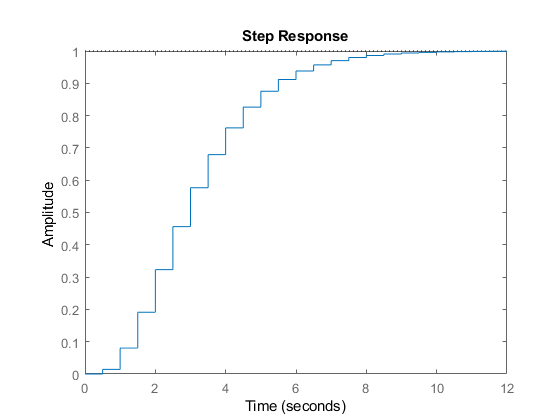

step(Gz)

P = pole(Gz) % to determine the poles of the discrete transfer function

P =    0.6065 + 0.0000i
   0.6065 - 0.0000i
   0.6065 + 0.0000i


Z = zero(Gz) % to determine the zeros of the discrete transfer function

Z =    -2.5785
   -0.1831


zpk(Gz);

## Problem One

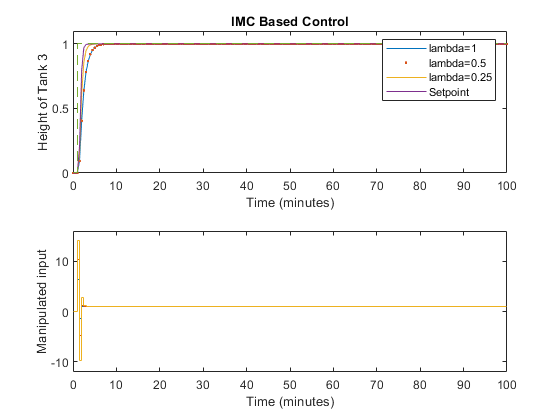

deltaT = 0.5; % sample time in minutes
x0 = zeros(3,3); % initial conditions
time = (0:0.5:100); % time vector in minutes

% All parameters were defined to have 3 rows and lengh(time)+3
% each row is used for each tuning parameter
y =  zeros(3,length(time)+3); % plant output
ym = zeros(3,length(time)+3); % model output
r = zeros(3,length(time)+3); % setpoint
rm = zeros(3,length(time)+3); % difference in deviation from setpoint (r)
u = zeros(3,length(time)+3); % manipulated input
d = zeros(3,length(time)+3); % difference in plant and model outputs (y-ym)

lambda = [1;0.5;0.25]; % tuning parameters
alpha = (exp(-0.5./lambda))';

for i = 1:3 % loop for each value of tuning parameter
for k = 1:length(time) % step change at time = 1
    if time(k) < 1
        r(i,k+3) = 0; % each row operation (i) is used for each tuning parameter
    else 
        r(i,k+3) = 1; % step change
    end
    % each row operation (i) is used for each tuning parameter
    ym(i,k+3) = modelresponse(ym(i,k+2), ym(i,k+1), ym(i,k), u(i,k+2), u(i,k+1), u(i,k));
    d(i,k+3) = y(i,k+3) - ym(i,k+3); 
    rm(i,k+3) = r(i,k+3) - d(i,k+3);
    
    % IMC based controller function created to compute manipulated input
    % for each row operation
    u(i,k+3) = IMC(u(i,k+2),alpha(i),rm(i,k+3),rm(i,k+2),rm(i,k+1),rm(i,k));
[~,xnew] = ode45(@(t,x) plantmodel(t,x,u(i,k+3)),[time(k) time(k)+deltaT], x0(:,i)); % ODE45 function
y(i,k+4) = xnew(end,end); % output as last value of xnew
x0(:,i)= xnew(end,:)'; % assigning states variables as input for next iteration
end
end

figure(1)
subplot(2,1,1)
plot(time,y(1,4:end-1),time,ym(1,4:end),'.')
hold on
plot(time,y(2,4:end-1))
plot(time,y(3,4:end-1))
stairs(time,r(1,4:end),'--')
hold off
xlabel('Time (minutes)')
ylabel('Height of Tank 3')
legend('lambda=1','lambda=0.5','lambda=0.25','Setpoint')
title('IMC Based Control')
ylim([0 1.1])

subplot(2,1,2)
stairs(time,u(1,4:end))
hold on
stairs(time,u(2,4:end))
stairs(time,u(3,4:end))
hold off
xlabel('Time (minutes)')
ylabel('Manipulated input')
ylim([-12 16])

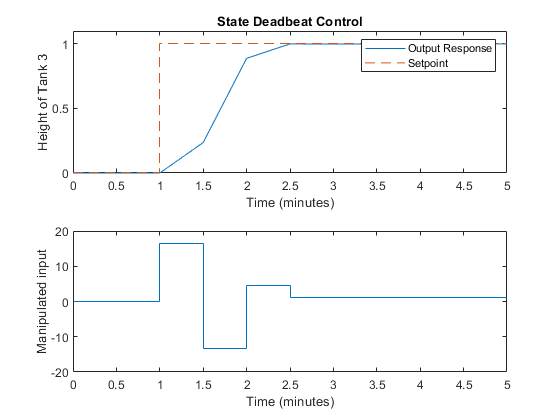

% State Deadbeat Control
clear all
deltaT = 0.5; % sample time in minutes
x0 = [0;0;0]; % initial conditions
time = (0:0.5:5); % time vector in minutes

% All Parameters defined to include additional 3 elements
y =  zeros(1,length(time)+3);
ym = zeros(1,length(time)+3);
r = zeros(1,length(time)+3);
rm = zeros(1,length(time)+3);
u = zeros(1,length(time)+3);

for k = 1:length(time) % step change at time = 1
    if time(k) < 1
        r(k+3) = 0;
    else 
        r(k+3) = 1;
    end
    ym(k+3) = modelresponse(ym(k+2), ym(k+1), ym(k), u(k+2), u(k+1), u(k));
    d = y - ym;
    rm = r - d;
    % State deadbeat function created to compute manipulated input
    u(k+3) = deadbeat(rm(k),rm(k+1),rm(k+2),rm(k+3)); 

[~,xnew] = ode45(@(t,x) plantmodel(t,x,u(k+3)),[time(k) time(k)+deltaT], x0); % ODE45 function
y(k+4) = xnew(end,end); % output as last value of xnew
x0= xnew(end,:)'; % assigning states variables as input for next iteration
end

figure(2)
subplot(2,1,1)
plot(time,y(4:end-1))
hold on
stairs(time,r(4:end),'--')
hold off
xlabel('Time (minutes)')
ylabel('Height of Tank 3')
legend('Output Response','Setpoint')
title('State Deadbeat Control')
ylim([0,1.1])

subplot(2,1,2)
stairs(time,u(4:end))
xlabel('Time (minutes)')
ylabel('Manipulated input')

% lower values of lambda increased the speed of response to attain

% stability but the state deadbeat still retains a faster response 

% compared to the IMC at lambda = 0.25 

## Problem two

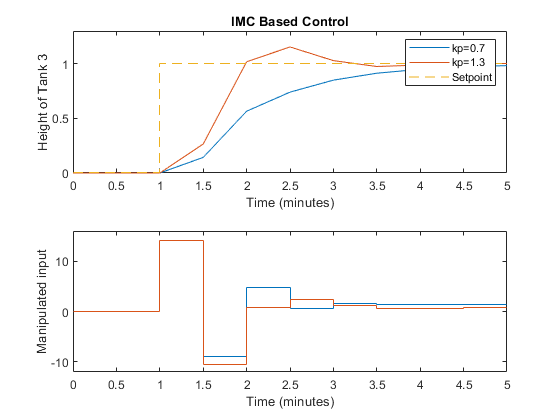

clear all
deltaT = 0.5; % sample time in minutes
x10 = [0;0;0];% initial conditions 1
x20 = [0;0;0]; % initial conditions 2
time = (0:0.5:5); % time vector in minutes

% All parameters were defined to have 2 rows and lengh(time)+3
% each row is used for each plant gain functions 
y =  zeros(2,length(time)+3);
ym = zeros(2,length(time)+3);
r = zeros(2,length(time)+3);
rm = zeros(2,length(time)+3);
u = zeros(2,length(time)+3);
d = zeros(2,length(time)+3);

lambda = 0.25;
alpha = exp(-0.5/lambda);
kp = [0.7;1.3]; % kp values used in each plant functions

for k = 1:length(time) % step change at time = 0
    if time(k) < 1
        r(:,k+3) = 0; % each each row operation is used for each of the kp values
    else 
        r(:,k+3) = 1; % each each row operation is used for each of the kp values
    end
    
    % model output and deviations from setpoint computed for each of the
    % rows which are then passed into the ODE function 
    ym(1,k+3) = modelresponse(ym(1,k+2), ym(1,k+1), ym(1,k), u(1,k+2), u(1,k+1), u(1,k));
    ym(2,k+3) = modelresponse(ym(2,k+2), ym(2,k+1), ym(2,k), u(2,k+2), u(2,k+1), u(2,k));
    d(1,k+3) = y(1,k+3) - ym(1,k+3);
    d(2,k+3) = y(2,k+3) - ym(2,k+3);
    rm(1,k+3) = r(1,k+3) - d(1,k+3);
    rm(2,k+3) = r(2,k+3) - d(2,k+3);
    
    % IMC based controller function created to compute manipulated input
    % for each row operation
    u(1,k+3) = IMC(u(1,k+2),alpha,rm(1,k+3),rm(1,k+2),rm(1,k+1),rm(1,k));
    u(2,k+3) = IMC(u(2,k+2),alpha,rm(2,k+3),rm(2,k+2),rm(2,k+1),rm(2,k));
    
    % each ODE is used for each of the row operations
[~,xnew1] = ode45(@(t,x) plantmodel1(t,x,u(1,k+3)),[time(k) time(k)+deltaT], x10); % ODE45 function
[~,xnew2] = ode45(@(t,x) plantmodel2(t,x,u(2,k+3)),[time(k) time(k)+deltaT], x20); % ODE45 function
y(1,k+4) = xnew1(end,end); % output as last value of xnew
y(2,k+4) = xnew2(end,end); % output as last value of xnew
x10= xnew1(end,:)'; % assigning states variables as input for next iteration
x20= xnew2(end,:)'; % assigning states variables as input for next iteration
end


figure(3)
subplot(2,1,1)
plot(time,y(1,4:end-1))
hold on
plot(time,y(2,4:end-1))
stairs(time,r(1,4:end),'--')
hold off
xlabel('Time (minutes)')
ylabel('Height of Tank 3')
legend('kp=0.7','kp=1.3','Setpoint')
title('IMC Based Control')
ylim([0 1.3])

subplot(2,1,2)
stairs(time,u(1,4:end))
hold on
stairs(time,u(2,4:end))
hold off
xlabel('Time (minutes)')
ylabel('Manipulated input')
ylim([-12 16])

% No offset was observed in the controller output

% An overshoot was rather observed when the gain kp = 1.3.

## Model Predicted Response

function ykm = modelresponse(yk1,yk2,yk3,uk1,uk2,uk3)
ykm = 1.82*yk1 - 1.104*yk2 + 0.2231*yk3 + 0.01439*uk1 + 0.03973*uk2 + 0.006794*uk3;
end

## Plant function

function xdot = plantmodel(t,x,u)
% State space equations 
xdot(1) = -x(1) + u;
xdot(2) = x(1) - x(2);
xdot(3) = x(2) - x(3);
xdot = xdot'; % converting the ODEs to column vector
end

% Plant model for kp = 0.7
function xdot = plantmodel1(t,x,u) 
% State space equations 
xdot(1) = -x(1) + 0.7*u;
xdot(2) = x(1) - x(2);
xdot(3) = x(2) - x(3);
xdot = xdot'; % converting the ODEs to column vector
end

% Plant model for kp = 1.3
function xdot = plantmodel2(t,x,u)
% State space equations 
xdot(1) = -x(1) + 1.3*u;
xdot(2) = x(1) - x(2);
xdot(3) = x(2) - x(3);

xdot = xdot'; % converting the ODEs to column vector

end


## IMC function

function uk = IMC(uk2,alpha,rk3,rk2,rk1,rk)

uk = (alpha*uk2) + 16.41497*(1-alpha)*(rk3 - 1.82*rk2 + 1.104*rk1 - 0.2231*rk);
end

## Deadbeat

function uk = deadbeat(rk3,rk2,rk1,rk)
uk = (rk - 1.82*rk1 + 1.104*rk2 - 0.2231*rk3)/0.0609;
end